P_t = 1.5*10^6; % W
G = 45; % dB
f_0 = 5.6*10^9; % Hz
T_0 = 290; % K
L_s = 6; % dB
F = 3; % dB
t = 0.2*10^-6; % τ sec

l = 5; ra = 1:.1:l; le = length(ra);
r = zeros(5, le);
f = 5000; g = 1; rc = 0.5:g:g*5;
for i = 1:le
    r(:, i) = radareqsnr(3e8/f_0, f*ra(i), P_t, ...
        t, 'RCS', rc, ...
    'Gain', G,'Ts', T_0*10^(F/10),'Loss', L_s);
end

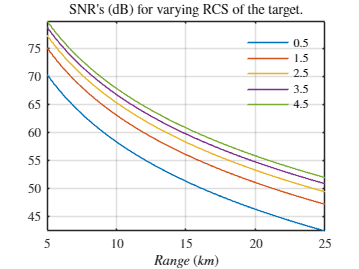

figure()
plot(f*ra/1e3, r');
xlabel('$Range$ $(km)$','interpreter','latex');
axis tight; axe(); grid on; % xline(I)
legend(num2str(rc'), ...
    'Location','Best','interpreter','latex')
title(['SNR''s (dB) for varying RCS of the ' ...
    'target.'],'interpreter','latex')
legend('boxoff')

function axe()
    axes = gca;
    axes.XAxis.TickLabelInterpreter = 'latex';
    axes.YAxis.TickLabelInterpreter = 'latex';
end